# Изучение тембра на практике

# 1. Извлечение гармоник из спектра

## Красницкий Никита

Темб - есть окрас музыкального заука, который может быть описан отношением амплитуд гармоник звука и их временными зависимостями. Для исследования тембра возьму в пример извлеченный звук гитарной струны и эксперементально найду математическое описание тембра. После чего попробую искусственно повлиять на тембр и синтезировать новое звучание.

Загружаю аудиофрагмент звукоизвлечения басовой ноты РЕ и вывожу на графиках левый и правый канал

clear all
close all
[x, fs] = audioread('Sound2.m4a');
sound(x, fs);

Что бы получить переменную соответствующую времени делаю следующее. Нахожу временной интервал между отчетами (dt). Через время между отчетами и кол-вом отчетов получаю время длительности сигнала (Ts). Создаю переменную времени (t)

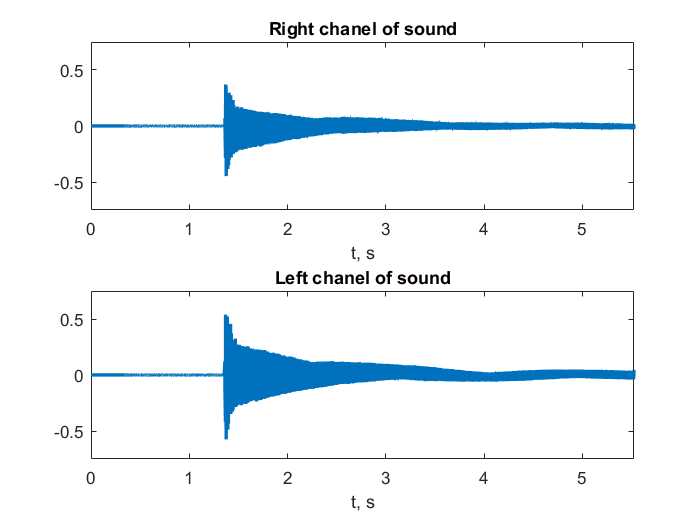

dt = 1/fs;
N  = length(x);
Ts = (N-1)*dt;
t  = 0:dt:Ts;

figure
subplot(2,1,1);
plot(t, x(:,1), 'LineWidth', 2);     
ylim([-0.75 0.75]);
xlim([0 t(end)]);
title('Right chanel of sound');
xlabel('t, s');

subplot(2,1,2);
plot(t, x(:,2), 'LineWidth', 2); 
ylim([-0.75 0.75]);
xlim([0 t(end)]);
title('Left chanel of sound');
xlabel('t, s');

## Спектр звука

Для этого сначала введу переменную частоты. Она находится в пределах от -fs/2 до fs/2 и имеет столько же отчетов, сколько имеет входной сигнал (N)

df = fs/N;
Fm = fs/2;
f = -Fm:df:Fm - df;

Найду спектры каждого из каналов и обозначу их как Rs и Ls. Их удобно смещенные модули обозначу как Rsa и Lsa (right/left spectrum absolute)

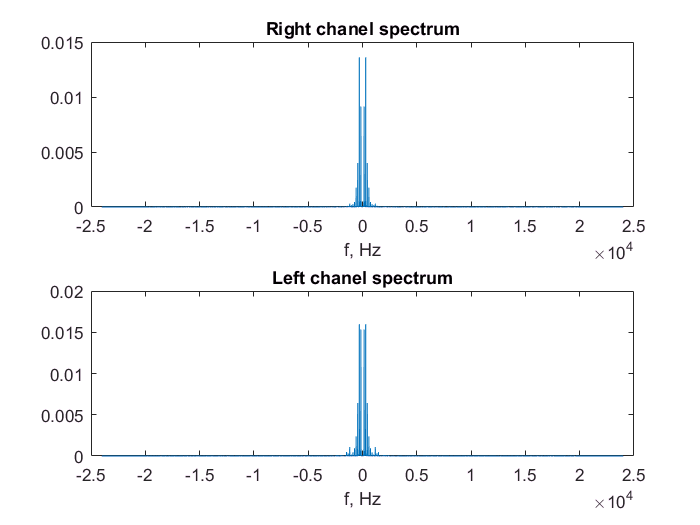

Rs = fft(x(:,1));
Ls = fft(x(:,2));

Rsa = abs(fftshift(Rs)) / N;
Lsa = abs(fftshift(Ls)) / N;

figure
subplot(2,1,1);
plot(f, Rsa);
title('Right chanel spectrum');
xlabel('f, Hz');

subplot(2,1,2);
plot(f, Lsa);
title('Left chanel spectrum');
xlabel('f, Hz');

Отобразим эти спектры в масштабе. 

Обозначим пороговую частоту, до которой нас интересует спектр (Fi - interest frequency) равной 2кГц

Fi = 2e3; 

Нужно найти индекс переменной частоты, которым будет ограничен график (Ni). Зависимость индекса переменной частоты (f) от требуемой частоты (Fi) линейна и может быть выражена следующим выражением для положительных частот

Ni = (N/2) * (1 + Fi/fs);

Для показа положительных частот на графике введу переменную частоты отображающую только положительные частоты ограничиваясь интересующей частотой (Fi).

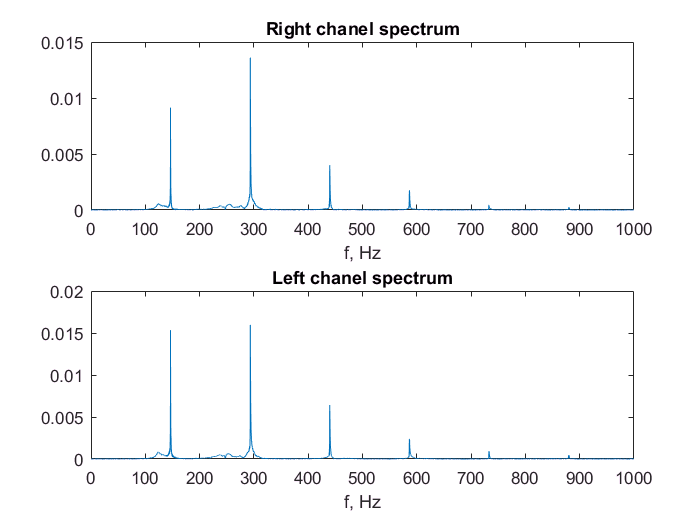

fp   = f  (N/2 + 1: Ni);
Rsap = Rsa(N/2 + 1: Ni);
Lsap = Lsa(N/2 + 1: Ni);

figure
subplot(2,1,1);
plot(fp, Rsap);
title('Right chanel spectrum');
xlabel('f, Hz');

subplot(2,1,2);
plot(fp, Lsap);
title('Left chanel spectrum');
xlabel('f, Hz');

Как видно из графиков спектр ноты РЕ наполнен кратными по частоте гармониками основного тона и характеристика их амплитуд не монотонно затухающая. 

Некоторые векторы достаточно длинные, удалю ненужные для сбережения памяти

clear Rs Ls Rsa Lsa f;

## Найду частоты каждой гармоники. 

Для этого воспользуюсь функцией поиска пиков и задам минимальное расстояние между пиками обеспечивающее игнорирование шума и прочего.

Вектор Fharm будет заполнен частотами гармоник, для перевода частот в индексы используется вектор Nharm. В вектор pks будут записаны высоты каждой гармоники.

[pks, Fharm] = findpeaks(Rsap, fp, 'MinPeakDistance', 100, 'MinPeakHeight', 5e-5);
Nip   = Ni - N/2;
Nharm = floor(Nip * Fharm/Fi);

Вывожу спектр правого канала

figure
area(fp, Rsap);

Поверх него накладываю фигуры, обозначающие положения пиков

hold on
plot(Fharm, pks, 'rv', 'MarkerFaceColor', 'r');

Создаю текст с частотами и накладываю текст на каждый пик спектра. Текст должен быть незначительно выше пиков для повышения читабельности, для чего был введен параметер масштаба yScaleAdd, поднимающий надписи на 5%

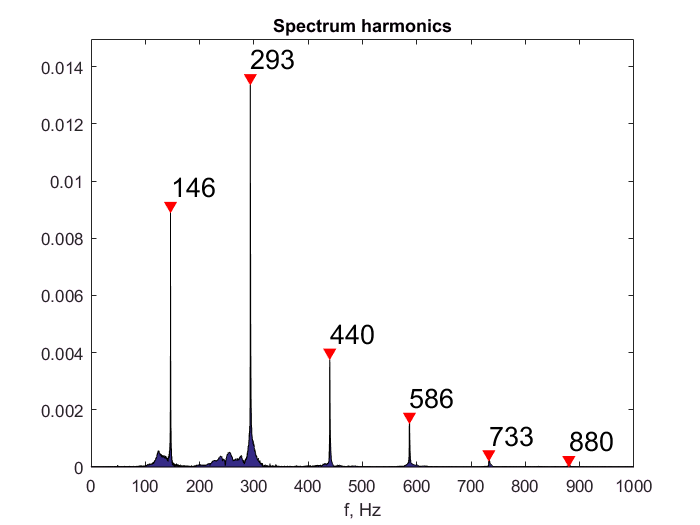

yScaleAdd = max(pks)*0.05; 

cellpeaks = cellstr(num2str(round(Fharm', 0)));
text(Fharm, yScaleAdd+pks, cellpeaks, 'FontSize', 16);
ylim([0 max(pks)+2*yScaleAdd]);
hold off
title('Spectrum harmonics');
xlabel('f, Hz');

Воспользовавшись таблицей соответствия нотам частот можно определить слышимые ноты

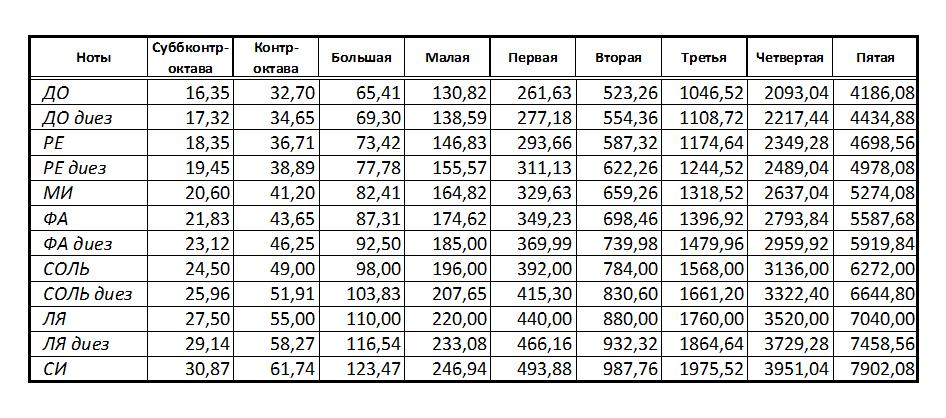

## Найду отношение гармоник к основному тону 

Из пиков видно, что основной тон соответсвует первой гармонике, основной тон обозначу как F0. (Fr - frequency ratio)

F0 = Fharm(1);
Fr = Fharm ./ F0;

strMessage = ['Harmonics ratio ', num2str(Fr)];
disp(strMessage);

Harmonics ratio1      2.0037      3.0025      4.0049      5.0037      6.0099


С точностью до тысячных частоты гармоник кратные основной.

# 2. Временная зависимость амплитуд гармоник

Как известно музыкальные звуки одних и тех же нот отличаются друг от друга на слух раличным тембром. Тембр описывается отношением гармоник и, как утверждают, во времени звучания тембр звука меняется и он меняется уникально для каждого инструмента. И именно по изменению тембра в промежутке аттаки звука человек различает ноту до гитары от ноты до скрипки. В этой части найдем эти временные зависимости тембра.

Такую зависимость можно найти используя оконное преобразование фурье и анализ гармоник, приведенный выше. Так можно получить амплитуды каждой гармоники в заданых временных промежутках и найти их временные изменения.